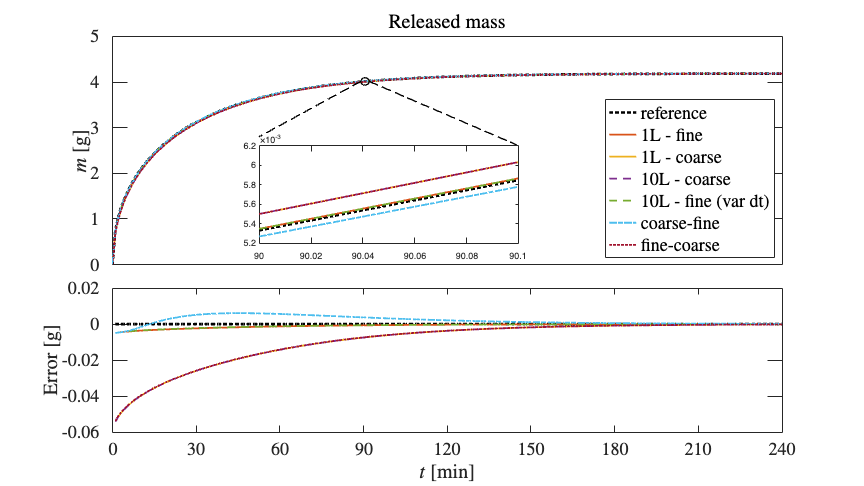

crate = 1/1000000;
load("test_academic/reference.mat", "M_released", "dt_mass", "T")
M0 = M_released*crate;
load("test_academic/L1_coarse.mat", "M_released")
M0a = M_released*crate;
load("test_academic/L1_fine.mat", "M_released")
M0b = M_released*crate;
load("test_academic/L10_coarse.mat", "M_released")
M1a = M_released*crate;
load("test_academic/L10_fine.mat", "M_released")
M1b = M_released*crate;
load("test_academic/L2_coarse_fine.mat", "M_released")
M2a = M_released*crate;
load("test_academic/L2_fine_coarse.mat", "M_released")
M2b = M_released*crate;
clear("M_released")

fig = figure();
fs = 20;

X = 0:dt_mass:T;
X = X / 60;
xmax = 60*4;
Xp = X;
Xp(1) = NaN;

%% SP1
ax = subplot(5,1,1:3);

plot(ax, X, cumsum(M0), 'k:', "LineWidth", 3.0)
hold(ax, "on")
plot(ax, X, cumsum(M0b), "LineWidth", 2.0)
plot(ax, X, cumsum(M0a), "LineWidth", 2.0)
plot(ax, X, cumsum(M1a), "LineWidth", 2.0, 'LineStyle','--')
plot(ax, X, cumsum(M1b), "LineWidth", 2.0, 'LineStyle','--')
plot(ax, X, cumsum(M2a), "LineWidth", 2.0, 'LineStyle','-.')
plot(ax, X, cumsum(M2b), "LineWidth", 2.0, 'LineStyle',':')
hold(ax, "off")

set(ax,'XTick',[]);
ylabel(ax, "$m$ [g]", 'Interpreter', 'latex', 'FontSize', fs);
title(ax, "Released mass", 'Interpreter', 'latex', 'FontSize', fs);

%yscale('log')

ax.TickLabelInterpreter = "latex";
ax.FontSize = fs;

xlim([0, xmax]);

%% INSET
axi = axes('Position', [.3, .5, .3, .2]);
x1 = 90;
x2 = 91;
x_center = (x1+x2)/2;
inset_idx = (X >= x1) & (X <= x2);
plot(axi, X(inset_idx), cumsum(M0(inset_idx)), 'k:', "LineWidth", 3.0)
hold(axi, "on")
plot(axi, X(inset_idx), cumsum(M0b(inset_idx)),  "LineWidth", 2.0)
plot(axi, X(inset_idx), cumsum(M0a(inset_idx)), "LineWidth", 2.0)
plot(axi, X(inset_idx), cumsum(M1a(inset_idx)),  "LineWidth", 2.0, 'LineStyle','--')
plot(axi, X(inset_idx), cumsum(M1b(inset_idx)),  "LineWidth", 2.0, 'LineStyle','--')
plot(axi, X(inset_idx), cumsum(M2a(inset_idx)),  "LineWidth", 2.0, 'LineStyle','-.')
plot(axi, X(inset_idx), cumsum(M2b(inset_idx)), "LineWidth", 2.0, 'LineStyle',':')
hold(axi, "off")

y_center = interp1(X, cumsum(M0), x_center);
r_x = 1.5;
r_y = y_center/50;
rectangle(ax, 'Position', [x_center - r_x, y_center - r_y, 2*r_x, 2*r_y], ...
          'Curvature', [1, 1], 'EdgeColor', 'k', 'LineWidth', 1.5);
hold(ax, "on");
plot(ax, [x_center - r_x, 52.5], [y_center, 2800000*crate], 'k--', 'LineWidth', 1.5);
plot(ax, [x_center + r_x, 145], [y_center, 2620000*crate], 'k--', 'LineWidth', 1.5);
hold(ax, "off");

xlim([90,90.1])

legend(ax, ["reference", "1L - fine", "1L - coarse", "10L - coarse", "10L - fine (var dt)", "coarse-fine", "fine-coarse"], "Location", 'southeast', 'Interpreter', 'latex', 'FontSize', fs)

%% SP2
ax = subplot(5,1,4:5);
div = M0;
div(1) = nan;
plot(ax, Xp, cumsum(M0)-cumsum(M0), 'k:', "LineWidth", 3.0)
hold(ax, "on")
plot(ax, Xp, cumsum(M0b)-cumsum(M0),  "LineWidth", 2.0)
plot(ax, Xp, cumsum(M0a)-cumsum(M0), "LineWidth", 2.0)
plot(ax, Xp, cumsum(M1a)-cumsum(M0),  "LineWidth", 2.0, 'LineStyle','--')
plot(ax, Xp, cumsum(M1b)-cumsum(M0),  "LineWidth", 2.0, 'LineStyle','--')
plot(ax, Xp, cumsum(M2a)-cumsum(M0),  "LineWidth", 2.0, 'LineStyle','-.')
plot(ax, Xp, cumsum(M2b)-cumsum(M0),  "LineWidth", 2.0, 'LineStyle',':')
hold(ax, "off")
%yscale('log')

%legend(ax, ["1L - fine", "1L - coarse", "10L - fine", "coarse-fine", "fine-coarse"], "Location", 'northwest')
set(ax,'XTick',[]);
ylabel(ax, "Error [g]", 'Interpreter', 'latex');
%title("relative error (w.r.t.\ reference)", 'Interpreter', 'latex');

ax.TickLabelInterpreter = "latex";
ax.FontSize = fs;
xlim([0, xmax]);


ax.TickLabelInterpreter = "latex";
ax.FontSize = fs;
xlim([0, xmax]);
ax.XTick = 0:30:xmax;

xlabel(ax, "$t$ [min]", 'Interpreter', 'latex')

fig.Position = [0 0 16*60 9*60];

exportgraphics(fig, "img/academic-release.png", 'Resolution', 300);
exportgraphics(fig, "img/academic-release.pdf", 'ContentType', 'image', 'Resolution', 900);

display("1L - fine "+ mean(abs(cumsum(M0b-M0))./cumsum(M0)*100, "omitnan"))

    "1L - fine 0.033994"



display("1L - coarse "+ mean(abs(cumsum(M0a-M0))./cumsum(M0)*100, "omitnan"))

    "1L - coarse 0.37554"



display("10L - coarse "+ mean(abs(cumsum(M1a-M0))./cumsum(M0)*100, "omitnan"))

    "10L - coarse 0.37554"



display("10L - fine (var dt) "+ mean(abs(cumsum(M1b-M0))./cumsum(M0)*100, "omitnan"))

    "10L - fine (var dt) 0.032615"



display("2L - coarse+fine "+ mean(abs(cumsum(M2a-M0))./cumsum(M0)*100, "omitnan"))

    "2L - coarse+fine 0.073036"



display("2L - fine+coarse "+ mean(abs(cumsum(M2b-M0))./cumsum(M0)*100, "omitnan"))

    "2L - fine+coarse 0.37366"



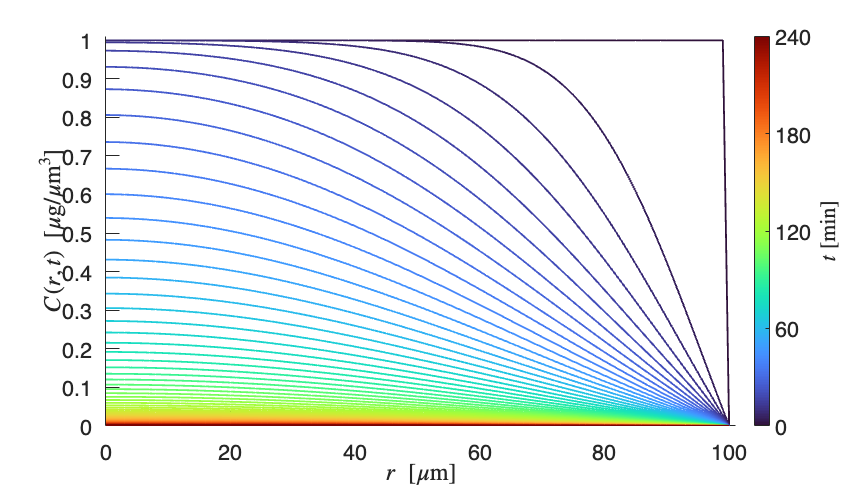

clear
fs = 24;
load("test_academic/L1_coarse_U.mat", "U_all", "dt_mass", "T");
U = zeros(length(U_all{1})+1, length(U_all));
for i = 1 : length(U_all)
    U(:, i) = [U_all{i}(:); 0];
end
U = U(:, 1:length(U_all));

fig = figure();
ax = axes('Parent', fig);

xs = 0:size(U,1)-1;      % x coordinates
ts = 0:size(U,2)-1;      % time indices
ts = ts * dt_mass / 60;
Nts = length(ts);

% Create colormap
cmap = turbo(Nts); % or parula, turbo, etc.

hold on;
for t_idx = 1:4:Nts
    plot(ax, xs, U(:,t_idx), 'Color', cmap(t_idx,:), 'LineWidth', 2);
end
hold off;

xlabel('$r$\ [$\mu$m]', 'Interpreter', 'latex', 'FontSize', fs);
ylabel('$C(r, t)$\ [$\mu$g/$\mu$m$^3$]', 'Interpreter', 'latex', 'FontSize', fs);
ax.FontSize = fs;
ylim([0, 1.01])
xlim([0, 101])
% title('u(x, t): coloured by timestamp');
colormap(cmap);
cb = colorbar;
cb.Ticks = linspace(0,1,5);
cb.TickLabels = round(linspace(ts(1), ts(end), 5));
cb.Label.String = '$t$ [min]';
cb.Label.Interpreter = 'latex';
cb.FontSize = fs;

fig.Position = [0 0 16*60 9*60];

exportgraphics(fig, "img/academic-profile.png", 'Resolution', 300);
exportgraphics(fig, "img/academic-profile.pdf");